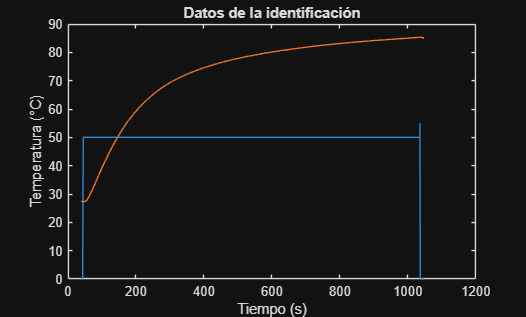

%% datos
clear; close all; clc;
%sacamos los datos del excel
%ubicacion='C:\Users\CESAR\Documents\MATLAB\control_pruebas\adquisicion\data\DatosGrafica_AdquirirQ1_20260525_113127.xlsx';
ubicacion='C:\Users\CESAR\Documents\MATLAB\control_pruebas\adquisicion\data\DatosGrafica_AdquirirQ1_20260530_195139.xlsx';
T=readtable(ubicacion,"Range",'A:G');
%time = readtable(ubicacion,"Range",'A:A');
%temp = readtable(ubicacion,"Range",'B:B');
%PWM = readtable(ubicacion,"Range",'D:D');
%adecuamos los datos
ts = T.Tiempo;
us = T.PWM1;
ys = T.Temperatura1;
plot(ts,us,ts,ys)
title('Datos de la identificación')
xlabel('Tiempo (s)')
ylabel('Temperatura (°C)')

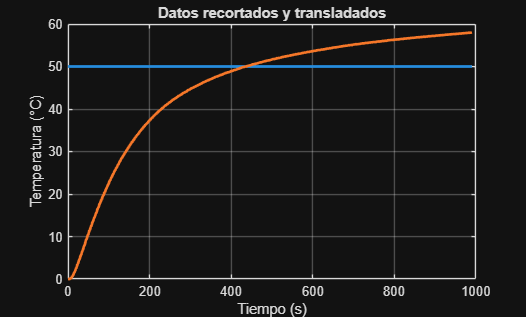

% recortar datos
b=mode(us); % Escalón donde se hizo la IDENTIFICACION

%Busca el momento exacto donde se insertó el escalón
i=1;
while(us(i)<b)
    i=i+1;
end
x1=i;
while(us(i)==b)
    i=i+1;
end
x2=i-1;

%Recortar datos hasta el origen
ur=us(x1:x2);
yr=ys(x1:x2);

tr=ts(x1:x2);
%trasladar los datos

ut=ur-us(1);
yt=yr-yr(2);

tt=tr-tr(1);

%Graficar escalón Trasladado
figure(2)
plot(tt,ut,tt,yt,'linewidth',2),grid
title('Datos recortados y transladados')
xlabel('Tiempo (s)')
ylabel('Temperatura (°C)')

%sistema de identificación

%systemIdentification();

% Evaluación de las respuetas de las fucniones de transferencia
load("C:\Users\CESAR\Documents\MATLAB\control_pruebas\adquisicion\Planta50_2.mat");
%datos de MATLAB
KpMatlab=P1D.Kp;
TauMatlab=P1D.Tp1;
TethaMatlab=P1D.Td;

GsMatlab=tf([0 KpMatlab],[TauMatlab 1]);
GsMatlab.IODelay=TethaMatlab


GsMatlab =
 
                    1.136
  exp(-8.76*s) * -----------
                 188.5 s + 1
 
Continuous-time transfer function.


% datos Excel
KpExcel=T.FODPT(1);
TauExcel=T.FODPT(2);
TethaExcel=T.FODPT(3);

GsExcel=tf([0 KpExcel],[TauExcel 1]);
GsExcel.IODelay=TethaExcel


GsExcel =
 
                1.16
  exp(-9*s) * ---------
              121 s + 1
 
Continuous-time transfer function.


%datos ingresados manual mente

% datos python
KpPython=1.16;
TauPython=185;
TethaPython=10;

GsPython=tf([0 KpPython],[TauPython 1]);
GsPython.IODelay=TethaPython;
% datos python IA
KpPythonIA=1.1371;
TauPythonIA=189.09;
TethaPythonIA=7.49;

GsPythonIA=tf([0 KpPythonIA],[TauPythonIA 1]);
GsPythonIA.IODelay=TethaPythonIA


GsPythonIA =
 
                    1.137
  exp(-7.49*s) * -----------
                 189.1 s + 1
 
Continuous-time transfer function.


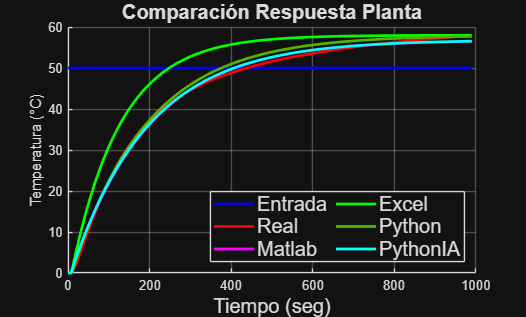

%step(GsMatlab);

%simulacion a la entrada

frecuencia=(max(tt)-min(tt))./(size(tt)-1);
frecuencia=frecuencia(1);
tt=min(tt):frecuencia(1):max(tt);

y=lsim(GsMatlab,ut,tt);
y1=lsim(GsExcel,ut,tt);
y2=lsim(GsPython,ut,tt);
y3=lsim(GsPythonIA,ut,tt);

out=[ut yt y y1 y2 y3];
texto=["Entrada" "Real" "Matlab" "Excel" "Python" "PythonIA"];
color=["b" "r" "m" "g" "#52B500" "c"];
selectColor=0;
figure(3)
hold on
for i=out
selectColor=selectColor+1;
p=plot(tt,i);
p.Color=color(selectColor);
p.LineWidth=2;

end
sizeletra=15;
hold off
legend()
title('Comparación Respuesta Planta','FontSize',15)
xlabel('Tiempo (seg)','FontSize',15)
ylabel('Temperatura (°C)')

lgd=legend(texto);
lgd.FontSize=15;
lgd.Location="southeast";
lgd.NumColumns=2;
grid on;